## Antenna Properties

Design antenna at frequency 77000000000Hz

antennaObject = design(patchMicrostrip,77000000000);
% Update substrate properties 
antennaObject.Substrate = dielectric('FR4');
antennaObject.Length = antennaObject.Length/2.2;
antennaObject.Width = antennaObject.Width/2.2;
antennaObject.GroundPlaneLength = antennaObject.GroundPlaneLength/2.2;
antennaObject.GroundPlaneWidth = antennaObject.GroundPlaneWidth/2.2;
antennaObject.FeedOffset = antennaObject.FeedOffset/2.2;

## Antenna Analysis

Define plot frequency 

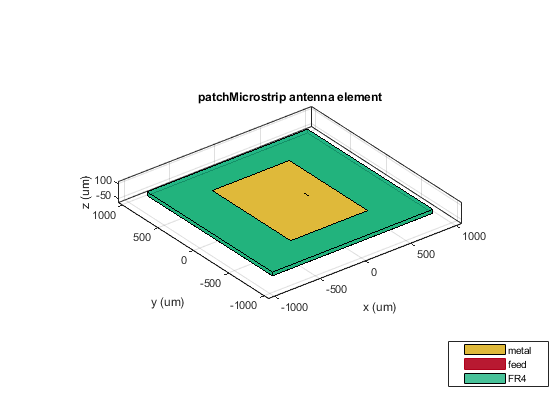

plotFrequency = 77000000000;
% Define frequency range 
freqRange = (69.3:0.77:84.7) * 1e9;
% show for patchMicrostrip
figure;
show(antennaObject) 

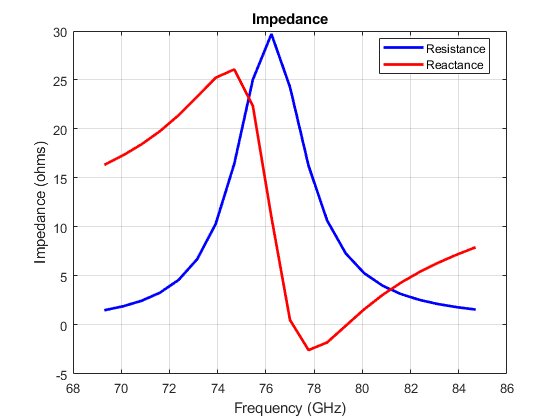

% impedance for patchMicrostrip
figure;
impedance(antennaObject, freqRange) 

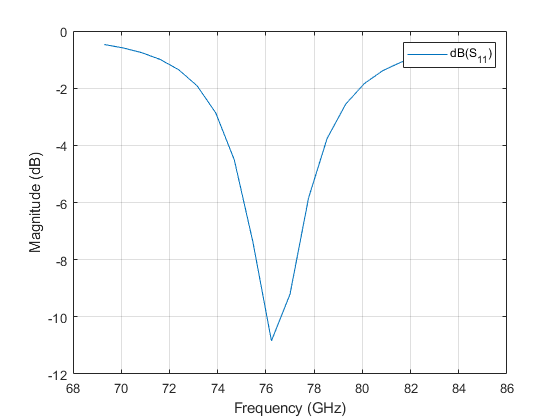

% s11 for patchMicrostrip
figure;
s = sparameters(antennaObject, freqRange); 
rfplot(s) 

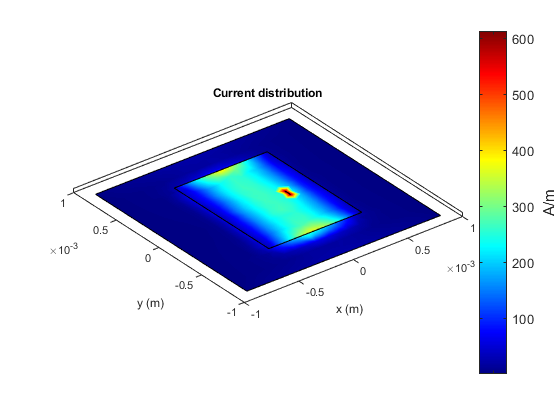

% current for patchMicrostrip
figure;
current(antennaObject, plotFrequency) 

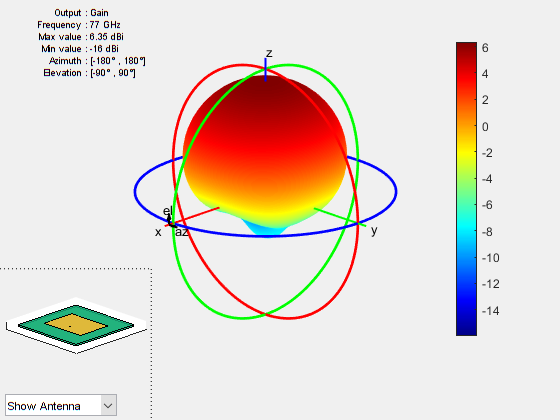

% pattern for patchMicrostrip
figure;
pattern(antennaObject, plotFrequency) 

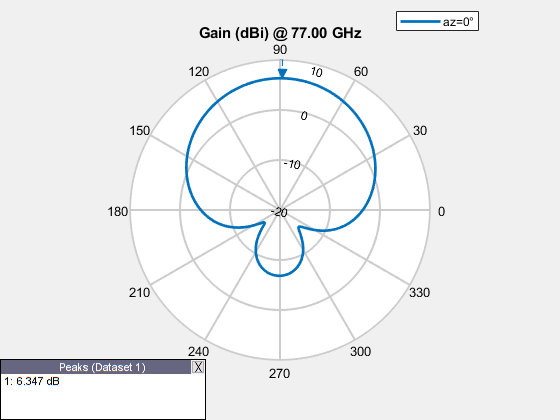

% elevation for patchMicrostrip
figure;
patternElevation(antennaObject, plotFrequency)